clear
clc

Create internal variables

m_i=1;
m=4;
motor_points=[[0.5,0.5];[0.5,-0.5];[-0.5,-0.5];[-0.5,0.5]];
I=0;
for i=1:length(motor_points)
    x=motor_points(i,1);
    y=motor_points(i,2);
    z=0;
    Ii=m_i*[y^2+z^2,-x*y,-x*z;-x*y,x^2+z^2,-y*z;-x*z,-y*z,x^2+y^2];
    I=I+Ii;
end
Ic=I

Ic =      1     0     0
     0     1     0
     0     0     2


M_RB=[m*eye(3),zeros(3);zeros(3),Ic]

M_RB =      4     0     0     0     0     0
     0     4     0     0     0     0
     0     0     4     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     2



Ic_diag = diag(Ic);
Jx = Ic_diag(1);
Jy = Ic_diag(2);
Jz = Ic_diag(3);
g = 9.81;

alpha = 1;
z = zeros(3,3);
I_inv = inv(Ic);
I3 = eye(3);

A = [ z, I_inv;
      z, -1/alpha*I3  ];

B = [ z;
      1/alpha*I3];

Q = eye(6);
R = 0.01 * I3;

K_lqr = lqr(A, B, Q, R)

K_lqr =    10.0000    0.0000   -0.0000   10.0000   -0.0000    0.0000
   -0.0000   10.0000    0.0000    0.0000   10.0000   -0.0000
   -0.0000    0.0000   10.0000    0.0000    0.0000    9.5357


## Trajectory

we want to go throught points

- [0, 0, 0]

- [1, 5, 1]

- [0, 5, 2]

- [10, 3, 3]

Xp = [0 1 0 10];
Yp = [0 5 5 3];
Zp = [0 1 2 3];
Pp = [0 0 0 0];

% MAX_POINT = 10;
% N_POINTS = 15;
% Xp = [0 randi(MAX_POINT, 1, N_POINTS)]
% Yp = [0 randi(MAX_POINT, 1, N_POINTS)];
% Zp = [0 randi(MAX_POINT, 1, N_POINTS)];
% Pp = [0 rand_angle(-2*pi, 2*pi, 1, N_POINTS)]

% Merge and transpose
W = reshape([Xp, Yp, Zp, Pp], size(Xp, 2), [])

W =      0     0     0     0
     1     5     1     0
     0     5     2     0
    10     3     3     0


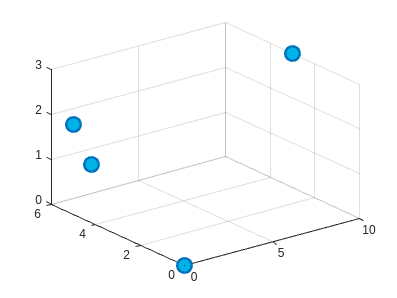


% Xp = randi(10, 1, 10);
% Yp = randi(10, 1, 10);
% Zp = randi(10, 1, 10);

figure(1)
plot3(Xp, Yp, Zp, 'o',...
    'LineWidth',2,...
    'MarkerSize',12,...
    'MarkerFaceColor',[0,0.7,0.9])
grid on

## Create trajectory polynomials

we have 4 waypoints, thus the structure will be


$$X=\;\left\lbrack w_1 ,\;w_2 ,\;w_2 ,\;w_3 ,\;w_3 ,\;w_4 ,\;v_{12-23} ,\;v_{23-34} ,\;a_{12-23} ,\;a_{23-34} ,\;v_0 ,v_T \right\rbrack$$


More generally


$$X=\;\left\lbrack w_1 ,\;\ldotp \ldotp \ldotp ,w_n ,v_{12} ,\;\ldotp \ldotp \ldotp ,v_{n-1,n} ,a_{12} ,\;\ldotp \ldotp \ldotp ,a_{n-1,n} ,v_0 ,v_T \right\rbrack$$



$$\left.n\in <2,\infty \right)$$



$${\backslash \textrm{#w}}_i \Rightarrow 2n-2$$



$${\backslash \textrm{#v}}_i \Rightarrow \left\lfloor \frac{{\textrm{#w}}_i +1}{2}\right\rfloor$$



$${\backslash \textrm{#a}}_i \Rightarrow {\backslash \textrm{#v}}_i$$



$$\backslash {\textrm{#j}}_i \Rightarrow \backslash {\textrm{#v}}_i$$



$$\backslash {\textrm{#s}}_i \Rightarrow \backslash {\textrm{#v}}_i$$


#### Total size:


$$\backslash \textrm{#X}=2n-2+4\left(\frac{2n-2}{2}-1\right)+2=6n-8$$


Where $w_n$ denotes the waypoint in appropriate axis, $v_{\textrm{mn}-\textrm{op}}$ is the difference in velocities while transfering between the trajectories, $a_{\textrm{mn}-\textrm{op}}$ is the acceleration in the point of transfer and $v_x$ is the starting and ending velocity.

%    W              v01-12 v12-23 a01-12 a12-23 v0 vT
dt = 10;
X = waypoints(Xp)'

X =      0
     1
     1
     0
     0
    10
     0
     0
     0
     0


Y = waypoints(Yp)';
Z = waypoints(Zp)';
P = waypoints(Pp)';

#### Generate the B matrix

B = generate_B(size(Xp, 2), dt)

B = 1.0e+10 *

    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0010         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0010         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0064    0.1280         0         0         0         0         0         0         0         0
         0         0 

#### Generate the trajectories

alpha_X = (B \ X);

alpha_Y = (B \ Y);

alpha_Z = (B \ Z);

alpha_P = (B \ P);


new_shape = [8, size(alpha_X,1)/8];

alpha_X = reshape(alpha_X, new_shape)'

alpha_X =          0   -0.0000    0.0000    0.0000    0.0011   -0.0002    0.0000   -0.0000
   -2.5763    1.8034   -0.5410    0.0902   -0.0080    0.0004   -0.0000    0.0000
  142.5529  -48.9918    7.0783   -0.5448    0.0238   -0.0006    0.0000   -0.0000


alpha_Y = reshape(alpha_Y, new_shape)';
alpha_Z = reshape(alpha_Z, new_shape)';
alpha_P = reshape(alpha_P, new_shape)';

#### Plot the generated trajectory

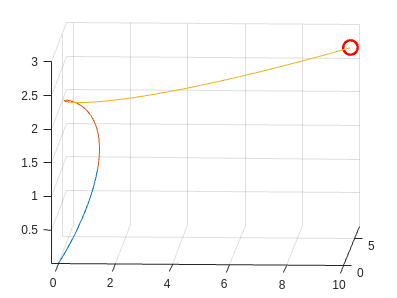

figure(2)

for i = 0 : size(Xp, 2)-2
	% [x,y,z] = funct(start, end, j, ax, ay, az)
	x = gen_trajectory(i*dt, (i+1)*dt, i+1, alpha_X);
	y = gen_trajectory(i*dt, (i+1)*dt, i+1, alpha_Y);
	z = gen_trajectory(i*dt, (i+1)*dt, i+1, alpha_Z);
	
    
    plot3(x, y, z);
    hold on;
    grid on;
end

plot3(Xp(1), Yp(1), Zp(1), 'o',...
    'LineWidth',2,...
    'MarkerSize',12,...
    'Color', 'g')

plot3(Xp(end), Yp(end), Zp(end), 'o',...
    'LineWidth',2,...
    'MarkerSize',12,...
    'Color', 'r')

grid on;
hold off;

Plot rotation fo the drone

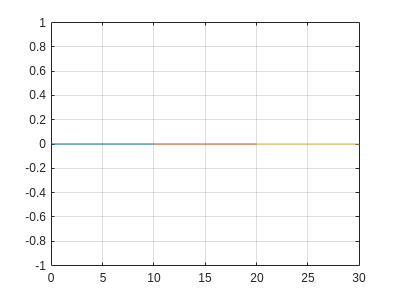

figure(2)

for i = 0 : size(Pp, 2)-2
	% [x,y,z] = funct(start, end, j, ax, ay, az)
	x = linspace(i*dt, (i+1)*dt);
	y = gen_trajectory(i*dt, (i+1)*dt, i+1, alpha_P);
	
    plot(x, y);
    hold on;
    grid on;
end

grid on;
hold off;

Plot their associated velocities

Vx = [];
Vy = [];
Vz = [];
size(alpha_X, 1)

ans = 3

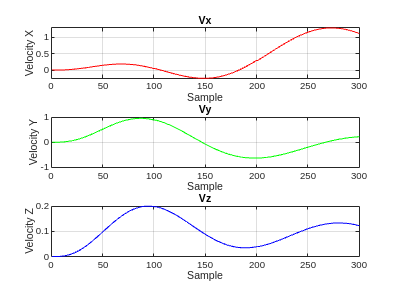

for i = 0 : size(alpha_X, 1)-1
	[vx,vy,vz] = gen_xyz_vel(i*dt, (i+1)*dt, i+1, alpha_X, alpha_Y, alpha_Z);
	Vx = [Vx, vx];
	Vy = [Vy, vy];
	Vz = [Vz, vz];
end

figure(3)
subplot(3,1,1);
plot(Vx, 'r');
title('Vx');
xlabel('Sample');
ylabel('Velocity X');
grid on

subplot(3,1,2);
plot(Vy, 'g');
title('Vy');
xlabel('Sample');
ylabel('Velocity Y');
grid on

subplot(3,1,3);
plot(Vz, 'b');
title('Vz');
xlabel('Sample');
ylabel('Velocity Z');
grid on

function [x] = gen_trajectory(s, e, j, pol)
    x = zeros(1,100);
    idx = 1;

    for t=linspace(s,e)
		T = [1 t t^2 t^3 t^4 t^5 t^6 t^7]';
        x(idx) = pol(j,:) * T;
        idx = idx+1;
    end
end

function [x,y,z] = gen_xyz_vel(s, e, j, ax, ay, az)
    x = zeros(1,100);
    y = zeros(1,100);
    z = zeros(1,100);
    idx = 1;
    
    for t=linspace(s,e)
		T = [0 1 2*t 3*t^2 4*t^3 5*t^4 6*t^5 7*t^6]';
        x(idx) = ax(j,:) * T;
        y(idx) = ay(j,:) * T;
        z(idx) = az(j,:) * T;
        idx = idx+1;
    end
end

function r = rand_angle(min, max, sz1, sz2)
	r = (max - min).*rand(sz1,sz2) + min;
end